    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:03        0.001                            4.0073
            1        1       00:00:03        0.001          3.8596                  
           50        9       00:00:33        0.001        0.002091           0.23713
          100       17       00:00:54        0.001      0.00061831          0.036579
          150       25       00:01:15        0.001      0.00010194          0.033137
          180       30       00:01:28        0.001       0.0001482          0.030888
Training stopped: Max epochs completed


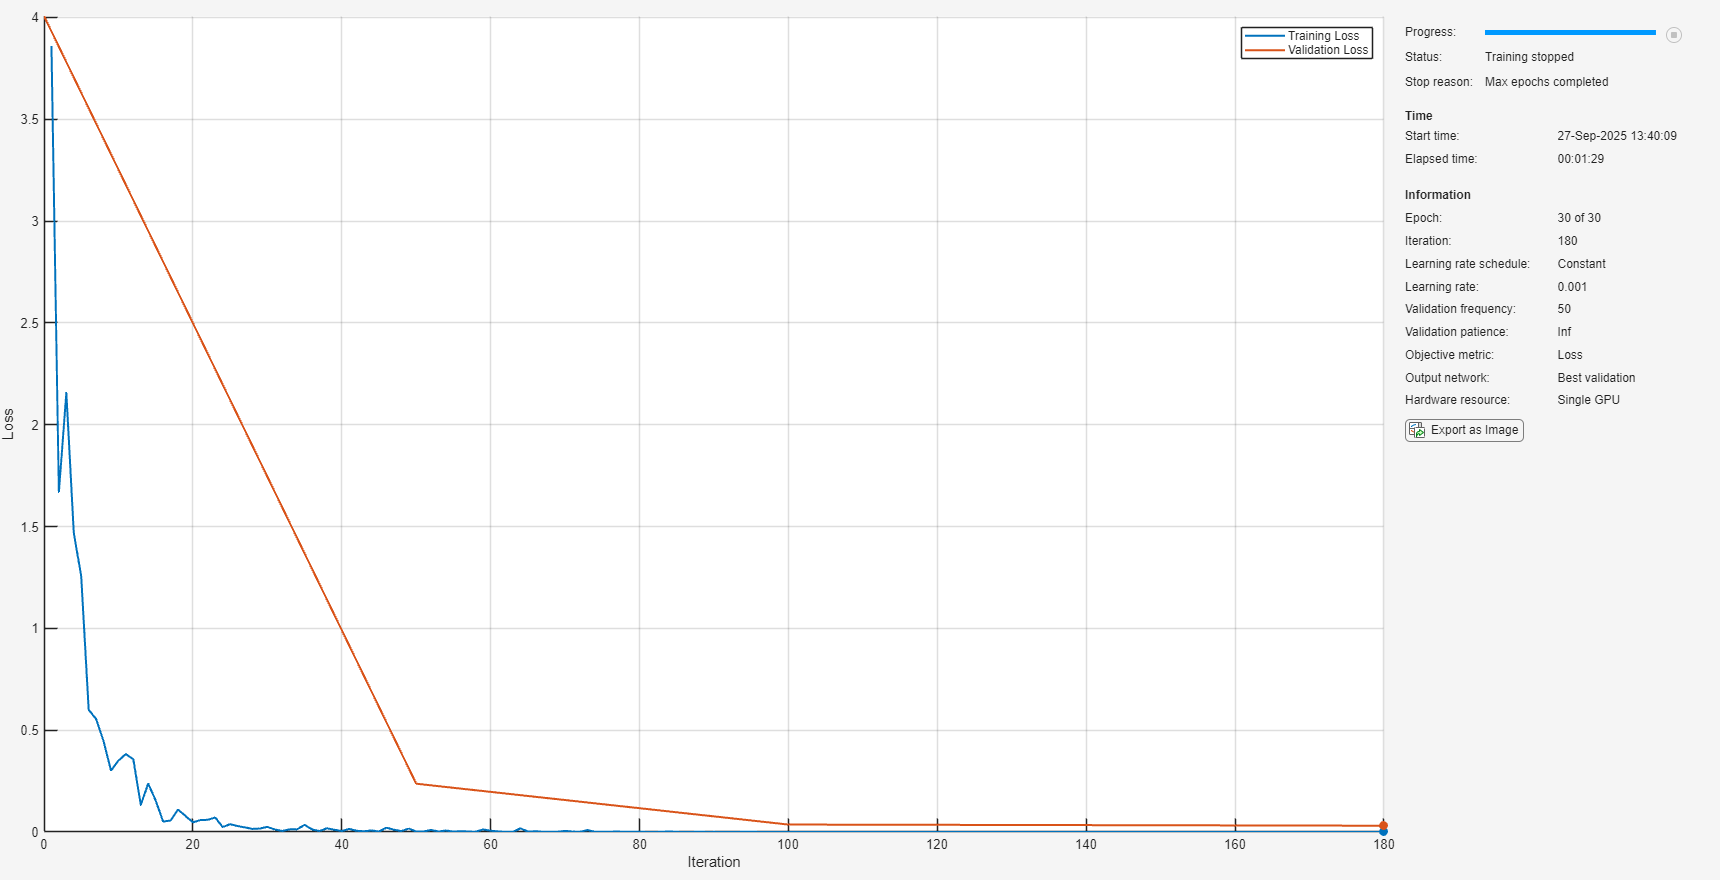

filePath = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Train";
imdsFasteners = imageDatastore(filePath, "IncludeSubfolders",true, "LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsFasteners, 0.8, "randomized");

augTrain = augmentedImageDatastore([224 224], imdsTrain);
augVal = augmentedImageDatastore([224 224], imdsValidation);

resnet18 = imagePretrainedNetwork("resnet18", "NumClasses", 19);

opts = trainingOptions("adam", "ValidationData",augVal, "Shuffle","every-epoch", "Plots","training-progress");

resnet18Fasteners = trainnet(augTrain, resnet18, "crossentropy", opts);

filenameTest = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Test"

filenameTest = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Test"

imdsTest = imageDatastore(filenameTest, "IncludeSubfolders", true, "LabelSource","foldernames");
augTest = augmentedImageDatastore([224 224], imdsTest);

classNames = categories(imdsTest.Labels);

testPreds = minibatchpredict(resnet18Fasteners, augTest);
testPredsClasses = scores2label(testPreds, classNames);
testAccuracy = nnz(testPredsClasses == imdsTest.Labels) / length(testPredsClasses)

testAccuracy = 0.9826

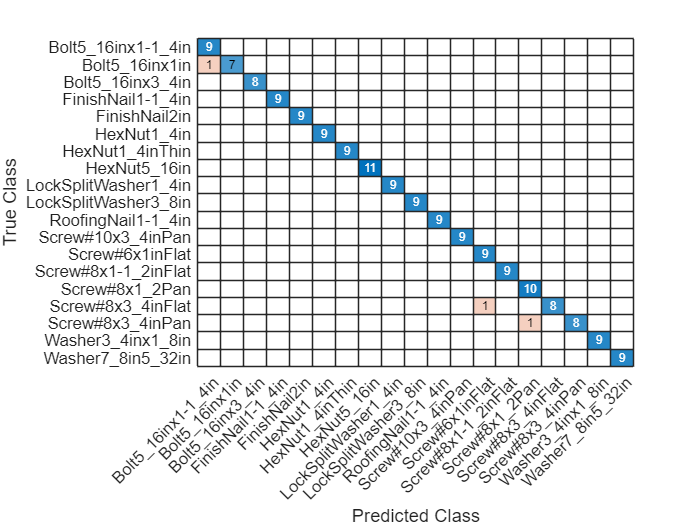

confusionchart(imdsTest.Labels, testPredsClasses)